# Main Program

## Circuito Matlab

clear all
close all
% Dati
path="Circuito-Matlab\";
load(path+"track_matlab.mat")
load(path+"/Point_new_map_1000.mat");
ss = 20;

%Modello
    % Modello Traxxas
    load("Models\Robot_model_TraxxasXTR.mat")
    k1 = 20;
    k2 = 12;
    % k1 = 5;
    % k2 = 2;
    % k1 = 60;
    % k2 = 42;

    % % Modello Hunter2
    % load('Models\Robot_model_Hunter2.mat')
    % k1 = 4;
    % k2= 3.5;

    % % Modello FR09
    % load('Models\Robot_model_FR09.mat')
    % k1=3;
    % k2=2.5;
    % % k1 = 4;
    % % k2= 3.5;

%Simulazione
    %Full-State Feedback
    open("Trajectory_tracking_full_state_feedback.slx");
    out = sim("Trajectory_tracking_full_state_feedback.slx");
    
    % %Runge-Kutta 2nd order
    % open("Trajectory_tracking_2nd_order.slx");
    % out = sim("Trajectory_tracking_2nd_order.slx");
    
    % %Runge-Kutta 4nd order
    % open("Trajectory_tracking_4th_order.slx");
    % out = sim("Trajectory_tracking_4th_order.slx");

%Plot
    % Circuit Result
    A = figure
    plot(x_in,y_in,'*','Color','red');
    hold on;
    plot(x_out,y_out,'*','Color','blue');

A =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


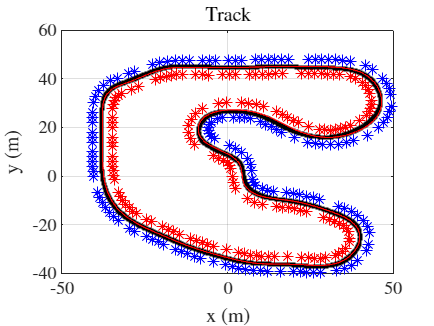

    hold on;
    plot(out.x.Data,out.y.Data,'.','Color','black');
    xlabel('x (m)');
    ylabel('y (m)');
    hold on;
    plot(x_values,y_values,'Color','red');
    hold on;
    grid;
    title('Track')
    
    %Plot Elaborato
    personal_plot6(out.error_x.Time,out.error_x.Data(1,:),'Time (s)','Error Position x-axis (m)','');

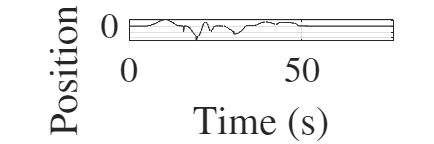

    personal_plot6(out.error_y.Time,out.error_y.Data(1,:),'Time (s)','Error Position y-axis (m)','');
    personal_plot6(out.error_norm.Time,out.error_norm.Data,'Time (s)','Error Position Norm (m)','');
    personal_plot6(out.v.Time,out.v.Data,'Time (s)','v (m/s)','');

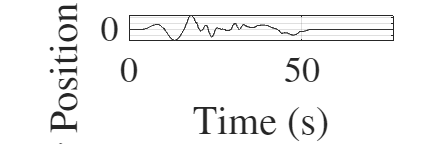

    personal_plot6(out.w.Time,out.w.Data,'Time (s)','w (rad/s)','');

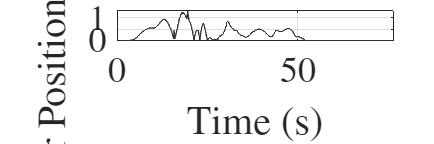

    personal_plot6(out.e1.Time,out.e1.Data,'Time (s)','Error y1 (m)',''); 

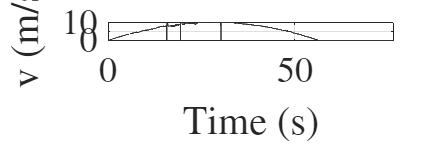

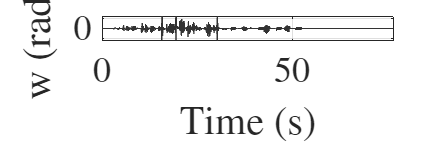

    personal_plot6(out.e2.Time,out.e2.Data,'Time (s)','Error y2 (m)',''); 

## Circuito FSI

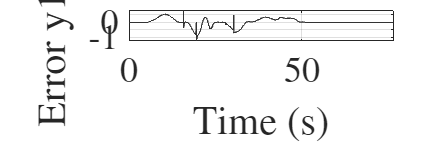

clear all

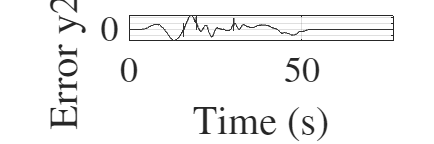

close all

% Dati
path="Circuito-UC\";
load(path+"track_autocross.mat")
load(path+"Point_500.mat");
ss = 5;

%Modello
     % Modello Traxxas
    load("Models\Robot_model_TraxxasXTR.mat")
    model = "Traxxar\";
    k1=40;
    k2=35;
    

    % % Modello Hunter2
    % load('Models\Robot_model_Hunter2.mat')
    % model = "Hunter\";
    % % k1=7;
    % % k2=6;
    % % k1=1;
    % % k2=0.5;
    % % k1=3.5;
    % % k2=2;
    % % k1=21;
    % % k2=18;
    % % k1=10;
    % % k2=8;
    % k1=7;
    % k2=9;

    % % Modello FR09 - Non regge la curvatura
    % load('Models\Robot_model_FR09.mat')
    % model= "FR09\";
    % k1=1;
    % k2=0.5;

%Simulazione
    %Full-State Feedback
    open("Trajectory_tracking_full_state_feedback.slx");
    out = sim("Trajectory_tracking_full_state_feedback.slx");
    
    % %Runge-Kutta 2nd order
    % open("Trajectory_tracking_2nd_order.slx");
    % out = sim("Trajectory_tracking_2nd_order.slx");
    
    % %Runge-Kutta 4nd order
    % open("Trajectory_tracking_4th_order.slx");
    % out = sim("Trajectory_tracking_4th_order.slx");

%Plot
    % Circuit Result
    A = figure
    plot(x_in,y_in,'*','Color','red');
    hold on;
    plot(x_out,y_out,'*','Color','blue');
    hold on;
    plot(out.x.Data,out.y.Data,'.','Color','black');
    xlabel('x (m)');
    ylabel('y (m)');
    hold on;
    plot(x_values,y_values,'Color','red');
    hold on;
    grid;
    title('Track')
    
    %Plot Elaborato
    personal_plot6(out.error_x.Time,out.error_x.Data(1,:),'Time (s)','Error Position x-axis (m)','') 
    personal_plot6(out.error_y.Time,out.error_y.Data(1,:),'Time (s)','Error Position y-axis (m)','')
    personal_plot6(out.error_norm.Time,out.error_norm.Data,'Time (s)','Error Position Norm (m)','')
    personal_plot6(out.v.Time,out.v.Data,'Time (s)','v (m/s)','')
    personal_plot6(out.w.Time,out.w.Data,'Time (s)','w (rad/s)','')
    personal_plot6(out.e1.Time,out.e1.Data,'Time (s)','Error y1 (m)','') 
    personal_plot6(out.e2.Time,out.e2.Data,'Time (s)','Error y2 (m)','') 

## Circuito Semplice

clear all
close all
% Dati
path="Circuito-Semplice\";
load(path+"track_new.mat")
load(path+"Point_New_Circ_600.mat");
ss = 5;

%Modello
    %  % Modello Traxxas
    % load("Models\Robot_model_TraxxasXTR.mat")
    % model = "Traxxar\";
    % k1=30;  %da trovare
    % k2=24;

    % % Modello Hunter2
    % load('Models\Robot_model_Hunter2.mat')
    % model = "Hunter\";
    % % k1 = 5;
    % % k2 = 2.5;
    % k1 = 10;
    % k2 = 5;
    % % k1 = 2.5;
    % % k2 = 0.5;

    % Modello FR09
    load('Models\Robot_model_FR09.mat')
    model= "FR09\";
    k1=2; 
    k2=3.5;

%Simulazione
    %Full-State Feedback
    open("Trajectory_tracking_full_state_feedback.slx");
    out = sim("Trajectory_tracking_full_state_feedback.slx");
    
    % %Runge-Kutta 2nd order
    % open("Trajectory_tracking_2nd_order.slx");
    % out = sim("Trajectory_tracking_2nd_order.slx");
    
    % %Runge-Kutta 4nd order
    % open("Trajectory_tracking_4th_order.slx");
    % out = sim("Trajectory_tracking_4th_order.slx");

%Plot
    % Circuit Result
    A = figure
    plot(x_in,y_in,'*','Color','red');
    hold on;
    plot(x_out,y_out,'*','Color','blue');
    hold on;
    plot(out.x.Data,out.y.Data,'.','Color','black');
    xlabel('x (m)');
    ylabel('y (m)');
    hold on;
    plot(x_values,y_values,'Color','red');
    hold on;
    grid;
    title('Track')
    
    %Plot Elaborato
    personal_plot6(out.error_x.Time,out.error_x.Data(1,:),'Time (s)','Error Position x-axis (m)','') 
    personal_plot6(out.error_y.Time,out.error_y.Data(1,:),'Time (s)','Error Position y-axis (m)','')
    personal_plot6(out.error_norm.Time,out.error_norm.Data,'Time (s)','Error Position Norm (m)','')
    personal_plot6(out.v.Time,out.v.Data,'Time (s)','v (m/s)','')
    personal_plot6(out.w.Time,out.w.Data,'Time (s)','w (rad/s)','')
    personal_plot6(out.e1.Time,out.e1.Data,'Time (s)','Error y1 (m)','') 
    personal_plot6(out.e2.Time,out.e2.Data,'Time (s)','Error y2 (m)','') 